clearvars;
%measurement settings
format shortG
xmin = -5;
xmax = 5;
ymin = -5;
ymax = 5;
zmin = 0;
zmax = 5;
xint = 0.5;
yint = 0.5;
zint = 0.5;
xtotal = ((xmax-xmin)/xint + 1);
ytotal = ((ymax-ymin)/yint + 1);
ztotal = ((zmax-zmin)/zint + 1);
%datasize = xtotal*ytotal*ztotal;
%magnet parameters
3/16

ans =        0.1875


1/8

ans =         0.125


diameter = 3/16*25.4 %mm

diameter =        4.7625


height = 1/8*25.4 %mm

height =         3.175


Br_max = 12100*0.1; %mT
mu_0 =  4*pi*10^-7*1000*1000; % mT mm/A^2
sensorheight = 35; %mm
%want M in A/m
M=Br_max;
B_t = pi*(diameter/2)^2*height*Br_max/(4*pi);
sensor_separation = 35; %mm

%this is for averaging the measurements at a specific location
% location = [];
% z = zmin;
% dataavg = [];
% 
% for k = 1:ztotal
%     zstr = sprintf('%.1f', z);
%     y = ymin;
% 
%     for j = 1:ytotal
%         ystr = sprintf('%.1f', y);
%         x = xmin;
% 
%         for i = 1:xtotal
% 
%             xstr = sprintf('%.1f', x);
%             filename = append('C:\Users\Brandon Nguyen\Documents\Gitub\magnetic-sensor-data\PIM06072023_sen1con\',xstr,'_',ystr,'_',zstr,'.data');
%             test = importdata(filename);
%             
%             bx1 = test.data(1:99,6);
%             by1 = test.data(1:99,7);
%             bz1 = test.data(1:99,8);
% 
%             bx2 = test.data(100:199,6);
%             by2 = test.data(100:199,7);
%             bz2 = test.data(100:199,8);
% 
%             bx3 = test.data(200:299,6);
%             by3 = test.data(200:299,7);
%             bz3 = test.data(200:299,8);
%             
%             bx4 = test.data(300:399,6);
%             by4 = test.data(300:399,7);
%             bz4 = test.data(300:399,8);
%             dataavg = [dataavg 
%                 [mean(bx1) mean(by1) mean(bz1) mean(bx2) mean(by2) mean(bz2) mean(bx3) mean(by3) mean(bz3) mean(bx4) mean(by4) mean(bz4)]];
%             location = [location
%                 [x y z]];
%            
%             x = x + xint;
%         end
%         y = y + yint;
%     end
%     z = z + zint;
% end

% writematrix(dataavg, 'C:\Users\Brandon Nguyen\OneDrive\Watanabe_Project\PIM06072023_sen1conaverages.txt');
% writematrix(location, 'C:\Users\Brandon Nguyen\OneDrive\Watanabe_Project\PIM06072023_sen1conlocations.txt')

location = importdata('C:\Users\Brandon Nguyen\OneDrive\Watanabe_Project\PIM06072023_sen1conlocations.txt');
dataavg = importdata('C:\Users\Brandon Nguyen\OneDrive\Watanabe_Project\PIM06072023_sen1conaverages.txt');

sen1 = dataavg(:,1:3) %bottom left sensor

sen1 =     -0.052972    -0.050935     0.096277
    -0.052674    -0.050979      0.09638
    -0.051843    -0.051075     0.096808
    -0.050757    -0.051169     0.097481
    -0.049159    -0.051228     0.098382
    -0.046994    -0.051332     0.099303
    -0.044492    -0.051473      0.10031
    -0.041597    -0.051665      0.10124
    -0.037183    -0.051868      0.10225
    -0.034094    -0.051938      0.10278


sen2 = dataavg(:,4:6) %bottom right sensor

sen2 =     -0.039063    0.0046905    0.0044685
    -0.039296    0.0046839    0.0044703
    -0.039505    0.0045698    0.0045733
    -0.039896    0.0046429    0.0048669
     -0.04033    0.0044649    0.0052295
    -0.040871    0.0044105    0.0056612
    -0.041488    0.0042868    0.0062506
     -0.04226    0.0042397    0.0068822
    -0.043326    0.0039867    0.0078757
    -0.044109     0.003833    0.0086929


sen3 = dataavg(:,7:9) %top left sensor (the magnet is centered above this sensor)

sen3 =    -0.0077421    -0.026388   -0.0016916
   -0.0078242     -0.02641   -0.0018539
   -0.0076979     -0.02657   -0.0018399
   -0.0076194    -0.026635   -0.0019239
   -0.0074536    -0.026762    -0.001888
   -0.0071238    -0.026899   -0.0018448
   -0.0068481    -0.026998   -0.0017137
   -0.0064857     -0.02711   -0.0017336
   -0.0058642     -0.02727   -0.0016941
   -0.0055245    -0.027357   -0.0015976


sen4 = dataavg(:,10:12) %top right sensor

sen4 =     -0.024879   -0.0059384    -0.030757
    -0.025017   -0.0060143    -0.030869
    -0.025042   -0.0061491    -0.030961
    -0.025128   -0.0061842    -0.030874
    -0.025231    -0.006338    -0.030805
    -0.025273   -0.0065264    -0.030749
    -0.025408   -0.0067875    -0.030751
    -0.025526   -0.0070417    -0.030672
    -0.025625   -0.0073795    -0.030609
    -0.025769   -0.0076962    -0.030468


X1 = [0 0 0] - location + [0 0 35];
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([0 0 1], 4851, 1);
expectB = B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)

expectB =      0.049256     0.049256      0.22517
     0.044746     0.049718      0.22773
     0.040109     0.050137      0.23005
     0.035357      0.05051      0.23213
     0.030502     0.050836      0.23394
     0.025557     0.051115      0.23549
     0.020538     0.051345      0.23677
     0.015457     0.051524      0.23777
     0.010331     0.051653      0.23849
     0.005173      0.05173      0.23892


testB = 2*sen1

testB =      -0.10594     -0.10187      0.19255
     -0.10535     -0.10196      0.19276
     -0.10369     -0.10215      0.19362
     -0.10151     -0.10234      0.19496
    -0.098318     -0.10246      0.19676
    -0.093989     -0.10266      0.19861
    -0.088984     -0.10295      0.20063
    -0.083194     -0.10333      0.20248
    -0.074366     -0.10374       0.2045
    -0.068187     -0.10388      0.20555


%fitting for the angle, the sensor is at (0,0,0)
ind = 10;
d_data = sen1;
loc = location + [0 0 35];
datasize = length(sen3);
dcostfun = @(v)anglecost(v, loc, d_data, B_t, datasize);
nonlcon = @con;
        
x0 = [0,0,0];
A = [];
b = [];
Aeq = [];
beq = [];
lb = [-1,-1,-1];
ub = [1,1,1];
[angle, fval] = fmincon(dcostfun, x0, A, b, Aeq, beq, lb, ub, nonlcon)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


angle =        0.7519      0.44642      0.48513


fval =        17.757


fval/datasize

ans =     0.0036606


sqrt(sum(angle.^2))

ans =             1


%fitting for the location using the angle from above, the sensor is at (0,0,0)
fixapreds = [];
fixafvalues = [];
for t = 1:length(sen3)
    B_data = sen1(t,:);
    costfun = @(v)loccost(v, angle, B_data, B_t);
    nonlcon = @con;

    x0 = [-5,-5,35];
    A = [];
    b = [];
    Aeq = [];
    beq = [];
    lb = [-20, -20, 30];
    ub = [20, 20, 60];
    [locs, fval] = fmincon(costfun, x0, A, b, Aeq, beq, lb, ub);
    fixapreds = [fixapreds; locs];
    fixafvalues = [fixafvalues; fval];
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

%fitting for the angle with 2x measured B, the sensor is at (0,0,0)
ind = 10;
d_data = testB;
loc = location + [0 0 35];
datasize = length(sen3);
dcostfun = @(v)anglecost(v, loc, d_data, B_t, datasize);
nonlcon = @con;
        
x0 = [0,0,0];
A = [];
b = [];
Aeq = [];
beq = [];
lb = [-1,-1,-1];
ub = [1,1,1];
[angle, fval] = fmincon(dcostfun, x0, A, b, Aeq, beq, lb, ub, nonlcon)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


angle =       0.51917      0.30824      0.79715


fval =         2.947


fval/datasize

ans =     0.0006075


sqrt(sum(angle.^2))

ans =             1


X1 = [0 0 0] - location + [0 0 35];
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([angle], 4851, 1);
faB = B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)

faB =     -0.017018    0.0082142      0.22025
    -0.021826    0.0080611      0.22009
    -0.026649    0.0078822      0.21967
    -0.031471    0.0076775      0.21897
    -0.036277    0.0074471      0.21799
    -0.041054    0.0071913      0.21675
    -0.045786    0.0069107      0.21523
    -0.050458    0.0066056      0.21345
    -0.055057    0.0062769       0.2114
    -0.059568    0.0059255      0.20909


expectB

expectB =      0.049256     0.049256      0.22517
     0.044746     0.049718      0.22773
     0.040109     0.050137      0.23005
     0.035357      0.05051      0.23213
     0.030502     0.050836      0.23394
     0.025557     0.051115      0.23549
     0.020538     0.051345      0.23677
     0.015457     0.051524      0.23777
     0.010331     0.051653      0.23849
     0.005173      0.05173      0.23892


fabdiff = expectB - faB

fabdiff =      0.066274     0.041042    0.0049207
     0.066573     0.041657    0.0076393
     0.066758     0.042254     0.010389
     0.066827     0.042832     0.013162
     0.066779     0.043389      0.01595
     0.066611     0.043924     0.018745
     0.066324     0.044434      0.02154
     0.065916     0.044919     0.024325
     0.065388     0.045376     0.027092
     0.064741     0.045805     0.029834


max(fabdiff)

ans =        0.1131     0.078299       0.1424


%fitting for the location using the angle from above with 2x measured B, the sensor is at (0,0,0)
fixapreds = [];
fixafvalues = [];
for t = 1:length(sen3)
    B_data = sen1(t,:);
    costfun = @(v)loccost(v, angle, B_data, B_t);
    nonlcon = @con;

    x0 = [-5,-5,35];
    A = [];
    b = [];
    Aeq = [];
    beq = [];
    lb = [-20, -20, 30];
    ub = [20, 20, 60];
    [locs, fval] = fmincon(costfun, x0, A, b, Aeq, beq, lb, ub);
    fixapreds = [fixapreds; locs];
    fixafvalues = [fixafvalues; fval];
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

X1 = [0 0 0] - location + [0 0 35];
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([angle], 4851, 1);
expectB = B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)

expectB =     -0.017018    0.0082142      0.22025
    -0.021826    0.0080611      0.22009
    -0.026649    0.0078822      0.21967
    -0.031471    0.0076775      0.21897
    -0.036277    0.0074471      0.21799
    -0.041054    0.0071913      0.21675
    -0.045786    0.0069107      0.21523
    -0.050458    0.0066056      0.21345
    -0.055057    0.0062769       0.2114
    -0.059568    0.0059255      0.20909


fixapreds

fixapreds =       -3.2407      -6.9164       40.524
      -3.1736      -6.9311       40.539
       -2.995      -6.9617       40.576
       -2.721      -6.9812        40.62
      -2.3397      -7.0007        40.69
      -1.8453      -7.0559       40.788
      -1.2721      -7.1221       40.889
     -0.61259       -7.236       40.994
      0.37729      -7.3834       41.161
       1.0592      -7.4627       41.279


fixafvalues

fixafvalues =    6.7613e-11
   8.4459e-11
   8.4533e-09
   1.3149e-09
   3.1012e-10
   2.2043e-10
   3.7665e-10
   9.0975e-09
    5.699e-09
   1.7896e-09


fixadiff = fixapreds - loc

fixadiff =        1.7593      -1.9164       5.5235
       1.3264      -1.9311       5.5392
        1.005      -1.9617       5.5764
      0.77902      -1.9812       5.6197
      0.66026      -2.0007       5.6897
      0.65474      -2.0559       5.7877
       0.7279      -2.1221       5.8886
      0.88741       -2.236       5.9935
       1.3773      -2.3834       6.1613
       1.5592      -2.4627       6.2792


max(fixadiff)

ans =        3.5481       4.8487       15.565


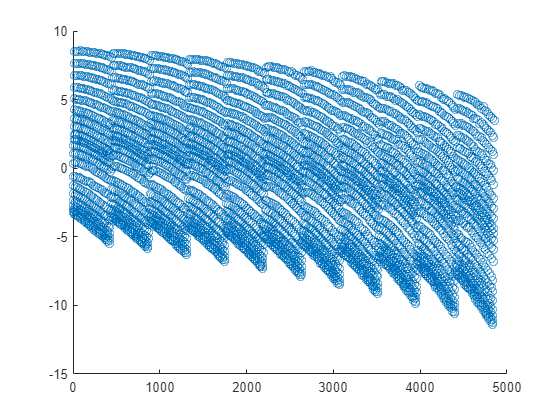

%predicted location using fixed angle
scatter(1:4851,fixapreds(:,1)) %x values

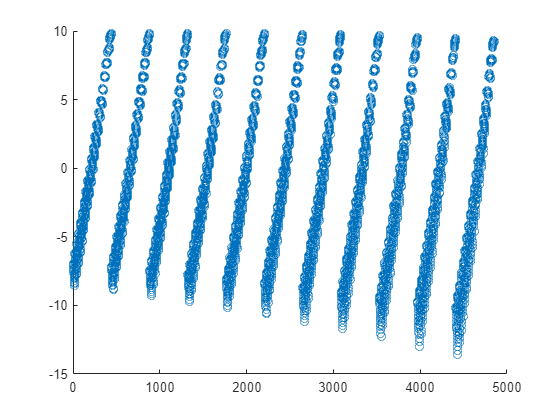

scatter(1:4851,fixapreds(:,2)) %y values

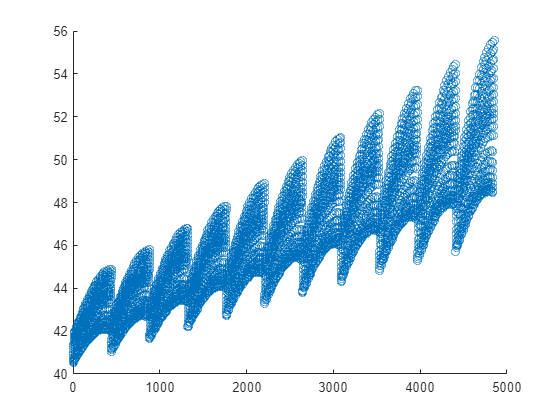

scatter(1:4851,fixapreds(:,3)) %z values

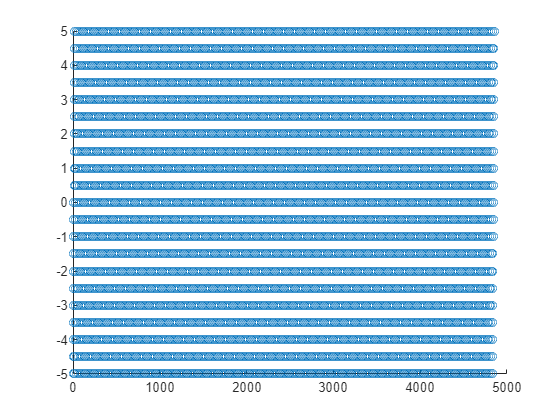

% scatter(1:4851,fixadiff(:,1))
% scatter(1:4851,fixadiff(:,2))
% scatter(1:4851,fixadiff(:,3))

%actual location of measurement
scatter(1:4851,loc(:,1))

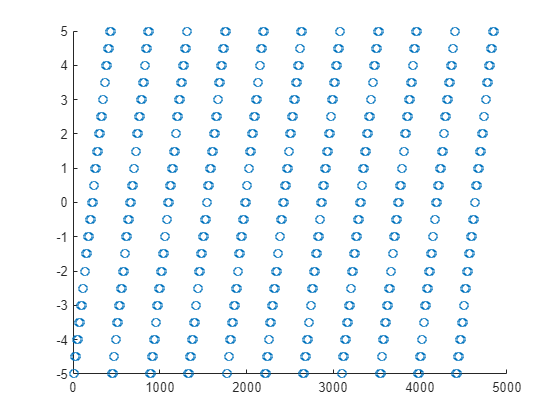

scatter(1:4851,loc(:,2))

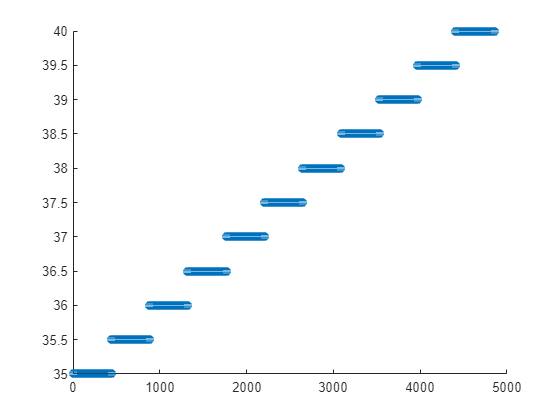

scatter(1:4851,loc(:,3))

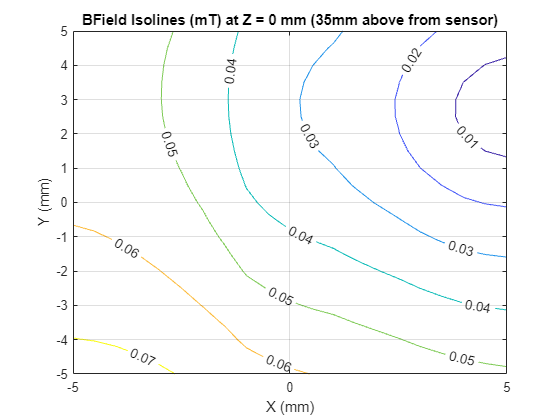

locavg = [location sen1];
format longG
zzero = find(abs(locavg(:,3)-0) < 0.1);

zzeromat = locavg(zzero,:);
zeroB = sqrt(sum(zzeromat(:,4:5).^2,2));
zeroB = reshape(zeroB, [sqrt(441) sqrt(441)]);
zerox = reshape(zzeromat(:,1), [sqrt(441) sqrt(441)]);
zeroy = reshape(zzeromat(:,2), [sqrt(441) sqrt(441)]);

contour(zerox, zeroy, zeroB, 'ShowText', 'on')
hold on;
grid on;
title('BField Isolines (mT) at Z = 0 mm (35mm above from sensor)')
xlabel('X (mm)')
ylabel('Y (mm)')
hold off

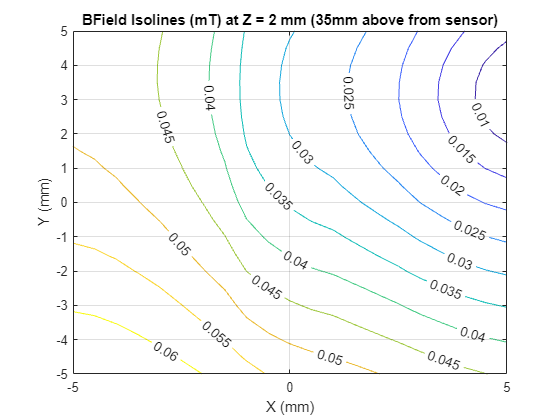

zzero = find(abs(locavg(:,3)-2) < 0.1);

zzeromat = locavg(zzero,:);
zeroB = sqrt(sum(zzeromat(:,4:5).^2,2));
zeroB = reshape(zeroB, [sqrt(441) sqrt(441)]);
zerox = reshape(zzeromat(:,1), [sqrt(441) sqrt(441)]);
zeroy = reshape(zzeromat(:,2), [sqrt(441) sqrt(441)]);

contour(zerox, zeroy, zeroB, 'ShowText', 'on')
hold on;
grid on;
title('BField Isolines (mT) at Z = 2 mm (35mm above from sensor)')
xlabel('X (mm)')
ylabel('Y (mm)')
hold off

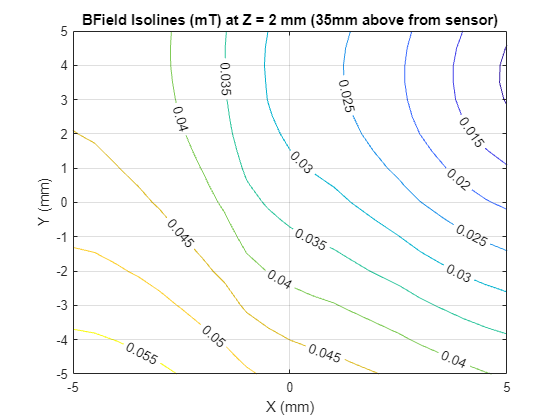

zzero = find(abs(locavg(:,3)-4) < 0.1);

zzeromat = locavg(zzero,:);
zeroB = sqrt(sum(zzeromat(:,4:5).^2,2));
zeroB = reshape(zeroB, [sqrt(441) sqrt(441)]);
zerox = reshape(zzeromat(:,1), [sqrt(441) sqrt(441)]);
zeroy = reshape(zzeromat(:,2), [sqrt(441) sqrt(441)]);

contour(zerox, zeroy, zeroB, 'ShowText', 'on')
hold on;
grid on;
title('BField Isolines (mT) at Z = 4 mm (35mm above from sensor)')
xlabel('X (mm)')
ylabel('Y (mm)')
hold off

06/06/2023

Meeting Notes

Rotate all sensors and repeat measurement to see if the same stretching happens.

Satwik has circuit board design done and ordered

Sensors are 25mm apart

Maybe try multi sensor with fixed angle (180,000 points) 

Put together Pi and Screen

Stronger magnet, Satwik says he found N55 strength, [https://buymagnets.com/product/neodymium-disc-magnets-n55/](https://buymagnets.com/product/neodymium-disc-magnets-n55/)

Figure out what magnet to buy for next week, look for even stronger magnets

% %fitting for the angle and location, the sensor is at (0,0,0)
% preds = [];
% fvalues = [];
% for t = 1:length(sen3)
%     B_data = sen3(t,:);
%     costfun = @(v)bothcost(v, B_data, B_t);
%     nonlcon = @con;
% 
%     x0 = [0,0,0, -5,-5,35];
%     A = [];
%     b = [];
%     Aeq = [];
%     beq = [];
%     lb = [-1,-1,-1,-7, -7, 0];
%     ub = [1,1,1, 7, 7, 50];
%     [mins, fval] = fmincon(costfun, x0, A, b, Aeq, beq, lb, ub, nonlcon);
%     preds = [preds; mins];
%     fvalues = [fvalues; fval];
% end

% anglepred = preds(:,1:3)
% locpred = preds(:,4:6)
% fvalues
% loc
% diff = locpred-loc
% max(diff)
% max(anglepred(:,1))
% max(anglepred(:,2))
% min(anglepred(:,3))

% %predicted location from fitting angle and location
% scatter(1:4851,locpred(:,1)) %x values
% scatter(1:4851,locpred(:,2)) %y values
% scatter(1:4851,locpred(:,3)) %z values
% % scatter(1:4851,fixadiff(:,1))
% % scatter(1:4851,fixadiff(:,2))
% % scatter(1:4851,fixadiff(:,3))
% 
% %actual location of measurement
% scatter(1:4851,loc(:,1))
% scatter(1:4851,loc(:,2))
% scatter(1:4851,loc(:,3))

% scatter(1:4851, sen3(:,1))
% hold on;
% grid on;
% xlim([0 100])
% hold off;
% scatter(1:4851, sen3(:,2))
% hold on;
% grid on;
% xlim([0 100])
% hold off;
% scatter(1:4851, sen3(:,3))
% hold on;
% grid on;
% xlim([0 100])
% hold off;

function a = anglecost(v, loc, B_data, B_t, datasize)
X1 = [0 0 0] - loc;
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([v(1) v(2) v(3)], datasize, 1);
a = sum(sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2));
end

function [c, ceq] = con(v)
c = [];
ceq = sqrt(sum([v(1) v(2) v(3)].^2, 2)) - 1;
end

function b = loccost(x, angle, B_data, B_t)
X1 = [-x(1) -x(2) -x(3)];
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem(angle, 1, 1);
b = sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2);
end

function b = bothcost(v, B_data, B_t)
H_0 = repelem([v(1) v(2) v(3)], 1, 1);
X1 = [-v(4) -v(5) -v(6)];
R1 = sqrt(sum(X1.^2, 2));
b = sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2);
end